# **Week 2**

## **Explore the “Uniform filter”. What is the difference with the “Gaussian filter”? What parameters would you choose to make the result of the uniform filter similar to the result from the Gaussian filter? Why can’t you make the results exactly the same?**

**Understanding Gaussian Filter**

The Gaussian filter is a filter named like this because uses the **Normal Distribution (ND) **to operate. Since this filter uses this particular statistical distribution there are different ways to implement this filter, including one method with the Fourier transform and others using a convolution matrix; for example using a finite number of samples (No) of the 3D-Normal Distribution (3DND)  as the convolution kernel. We are going to explain this last one.

The Normal Distribution is described by the next equation, depending on one variable:


$$f\left(x\right)=\frac{1}{\sqrt{2\pi \sigma^2 }\;}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$$


if we display this function (with mu = 0, sigma = 1) we can see a Gaussian Bell:

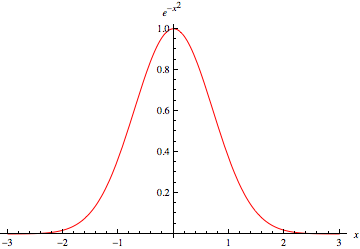

This function has many statistical and mathematical properties that makes it interesting, like the **Central Limit Theorem**. This Theorem states that when random independent variables are added to a sample, the properly normalized sum of the variables tend to the ND. That allows to model a lot of different samples using this function. But, in our case, we will use a 3DND that has analogous properties in R^3. 

Being *f *the ND function and *g *the 3DND function, our equation is the next (with $\mu =0$). 


$$g\left(x,y\right)=f\left(x\right)*f\left(y\right)=\frac{1}{\sqrt{2\pi \sigma^2 }\;}e^{-\frac{x^2 }{2\sigma^2 }} *\frac{1}{\sqrt{2\pi \sigma^2 }\;}e^{-\frac{y^2 }{2\sigma^2 }} \;$$


You can notice that this 3DND is just the multiplication of two regular NDs depending on two different variables. 

The graphical representation looks like this (with $\sigma =1$):

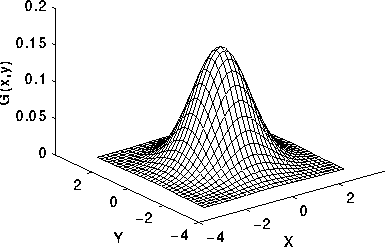

Because we are working with an Image, which is matrix, we are forced to work in a discrete set. We need to convert our function (continuous) into discrete information for our matrix. For doing that, we will take samples around the function. We will use ***x *****and *****y***** as distance in pixels from the central cell of the matrix**, with $\left(x,y\right)=\left(0,0\right)$ to calculate the values of the convolution matrix. Usually $\mathrm{No}=3\;\mathrm{or}\;\mathrm{No}=5$, to take samples in order to fill a 3x3 or 5x5 matrix for our convolution. For example, sampling the 3DNM with $\mu =0,\;\sigma =0\ldotp 84089642\;\mathrm{and}\;\mathrm{No}=7$ produces the following results:

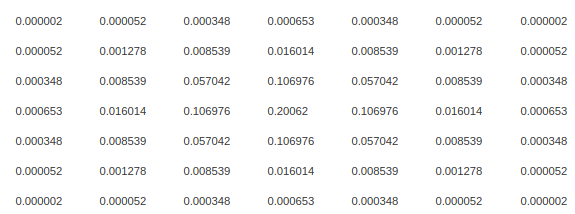

We can see that the probability distribution generates a convolution matrix in which the weight of each pixel decreases with the distance from the central value, that has the highest weight. We can also observe that the sum over all the matrix is equal to 1.

$\sigma$ or Standard Deviation describes the dispersion of data. In a non-dispersed sample where all values are the average, the Standard Deviation is 0.  As we increase $\sigma$ we can see that the bell expands in the sides and decrease in high and width in the center. Because of that, the Gaussian filter convolutions gives more weight to further pixels and less to (the) central pixel as sigma increases. That explains why when we apply a bigger sigma the image is more blurred: If the surroundings are different (corresponding usually to edges in the image) the calculated pixel is more likely to significantly change. With a small $\sigma$ the opposite happens: central values increase in its weight and further ones tend to 0.

With a $\mu =0,\;\sigma =10\;\textrm{and}\;\textrm{No}=7$ we get the following sample:

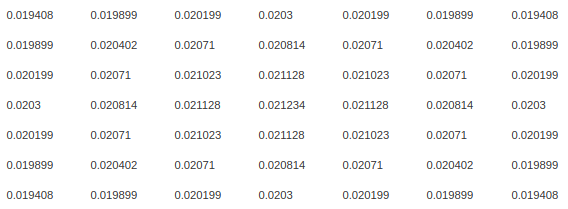

Notice the difference between the sample above. As explained, the central value is smaller and the values that are further have more weight now. 

Of course, since the probabilities using the 2DND are calculated using a two-variable integral in a continuous space and we are in a discrete space, this values are just an approximation:

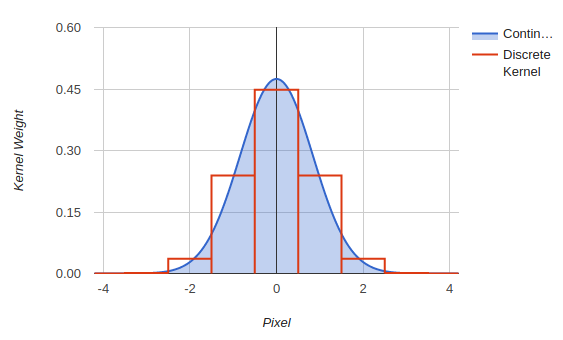

In the image we are doing an approximation of the area under the function ND. We will do the analogous in $R^3$ with the 2DND. The precision usually depends on the number of samples per pixel and the used method to generate the matrix.

**Understanding Uniform Filter**

The uniform filter is much more easier to understand. It uses a predefined convolution matrix that calculates an average intensity for a matrix of pixels. In this matrix (almost) all the pixels have the same weight.

Two examples are shown:

- Triangular uniform filter:

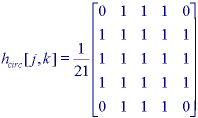

- Rectangular uniform filter:

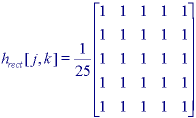

**Difference between the filters and how to get the same result**

First of all we need to get information about the command *gaussf* and *unif:*

help gaussf

--- gaussf not found. Showing help for gaussfir instead. ---

 gaussfir   Gaussian FIR Pulse-Shaping Filter Design.
 
 
    H=gaussfir(BT) designs a low pass FIR gaussian pulse-shaping filter.
    BT is the 3-dB bandwidth-symbol time product where B is the one-sided
    bandwidth in Hertz and T is in seconds.
 
    H=gaussfir(BT,NT) NT is the number of symbol periods between the start
    of the filter impulse response and its peak. If NT is not specified, 
    NT = 3 is used.
 
    H=gaussfir(BT,NT,OF) OF is the oversampling factor, that is, the number
    of samples per symbol. If OF is not specified, OF = 2 is used.
 
    The length of the impulse response of the filter is given by 2*OF*NT+1.
    Also, the coefficients H are normalized so that the nominal passband
    gain is always equal to one.
 
 

help unif


unif not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



We can observe that for the *gaussf *filter we can choose the method for implementing the convolution kernel *gaussfir*, *gaussiir*, *gaus*, *best* and we also have the $\sigma$ parameter for creating our 2DND function. 

In the *uniform* function we can choose the size of the filter and the shape of the filter, having *rectangular*, *elliptic* and *diamond* as possibilities.

To provide an answer to the question of producing the same result with the two filters we will first use the trivial case of each filter (the case in which the image does not change):

- **Trivial case**

Knowing the explained before, now we know that when applying the gaussian filter with $\mu =0\;\mathrm{and}\;\sigma =0$ or when applying the uniform filter with a convolution matrix of 1x1 we get the same image (because both produce a convolution matrix with a 1 in its center). Thus, we achieved to get the same output from both filter using the same image.

cermet = readim('cermet');

Undefined function or variable 'readim'.

isequal(dip_array(gaussf(cermet, 0)), dip_array(unif(cermet, 1))) 

Note that actually setting $\sigma =0$ as a parameter produces division by 0, but no problem is found because matlab takes sigma as a double, so the number is never 0 exactly, just a floating point number near to it: $\sigma \approx 0$ .

- **Extreme case**

This case uses the properties of $\sigma$ from the ND. 

If we model a 2DND with $\sigma \to \;\infty$ it means that data is almost equally distributed between values, having a really flat, but really long 2DND. In this case, **this function is similar to the function that models the uniform filter**.

We can achieve getting the same output from both images modifying  $\sigma$. Since $\sigma$ describes the dispersion of data and the shape of our function, we can think about the convolution matrix of the uniform filter as a 2D function where the dispersion is maximum, thus, the plot of the uniform filter matrix is a plane in $R^3$. 

We can see an analogous example in $R^2$:

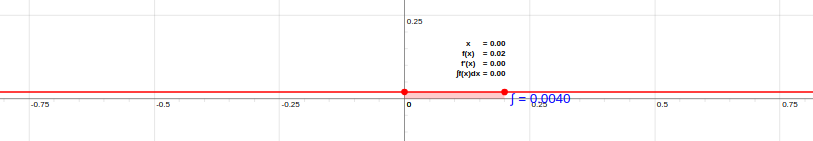

This plot corresponds to a ND function where $\sigma =20$*. *The plot is almost flat, so if we sample around $x=\mu$, we will probably get really similar values for every cell in our matrix (even if we are far away from the coordinate origin). Since the values are normalized, that means that all the pixels in the convolution matrix of the Gaussian filter will have the same weight, the same that happens in the uniform matrix. So, in practise **Gaussian filter behaves a a uniform square filter when sigma tends to be a big number.**

When we apply the filter and compare the results we can see that the filtered image is not the same, though:

unif(cermet, 7)  % apply uniform filter with a convolution size mask of 7
figure;
gaussf(cermet, 10000)  % apply Gauss filter with a very big sigma, so the distribution data tends to be uniform.

If we take a look at the images we can see that they are clearly different.  The Gaussian filter image now is completely blurred so the image is just unrecognizable. The uniform filter image is just a little more blurred than the original. 

We were expecting the same results from both filters but the result is completely different. We thought of two reasons:

- The first reason that we can think about is the size of the convolution matrix used by the Gaussian filter. The size of the convolution matrix is usually automatically set to $3\sigma$, so with a big sigma we are taking in account really further pixels from the center pixel, having a much bigger convolution matrix than in the uniform filter.  Note then that this parameter is **derivative **so we can not set it directly, at least in this implementation of the Gaussian filter of the DIPlib.

- The uniform filter works with integers and the Gaussian filter works with reals. In cases where this filters are supposed to produce the same results, Gauss filter gives better precision, so the results are considered different by Matlab.

Knowing that, we will do a test in which we try to avoid the stated before. 

We will apply uniform filter with a big kernel size, and the Gaussian filter with a big sigma (therefore, having a big kernel size too) to the same image. Then, we are going to round values to the next Integer from the Gaussian filter output and we will compare it to the output of the Uniform filter: 

isequal(round(dip_array(gaussf(cermet, 800)), 0), dip_array(unif(cermet, 2600)))

The output is the same, then.

Now we know that the difference between the output of our two filters when$\sigma \to \infty$ in the Gaussian filter is due to differences in the implementation, so we will use another function that gives us more flexibility.

*fspecial *is a function that allows to create your own convolution matrix using different filters. We are going to create a convolution matrix of 5x5 using the Gaussian filter with $\sigma \to \infty$. We will also generate a uniform filter using the same function and we will compare resuts:

gaussian_convolution_sigma_inf = fspecial('gaussian', [5 5], 1000)
uniform_convolution = (1/25)*ones(5,5)
uniform_convolution_auto = fspecial('average', 5)
isequal(uniform_convolution, uniform_convolution_auto)
isequal(uniform_convolution, gaussian_convolution_sigma_inf)

We can see that the three matrix contain the same values, confirming our hypothesis. Also the two uniform matrix are the same. 

When we compare the uniform kernel with the Gaussian kernel, though, we get false. The difference between the values of the two convolutions is in the order of ${10}^{-7}$ and is due precision differences because of the sampling of the 2DND:

tmp = uniform_convolution - gaussian_convolution_sigma_inf;
tmp

As we increase sigma, differences between convolution matrix are smaller. 

tmp = uniform_convolution - fspecial('gaussian', [5 5], 10000)

Using the round function at the required precision level we get the same output. 

isequal(uniform_convolution, round(gaussian_convolution_sigma_inf, 6))

**Conclusion**

- Uniform filter uses a predefined matrix where (almost) all the pixels have the same wight. When the convolution matrix size is set to 1 the filter does not produce any change.

- Gaussian filter uses samples from a 2DND function to build its convolution matrix. $\sigma$ describes the dispersion of data and therefore the shape of the 2DND. When $\sigma \approx 0$ all the values are in the average, and the filter does not produce any change. When $\sigma \to \infty$the Gaussian filter behaves like a uniform rectangular filter. 

**References & Sources**

- [Smoothin operations](http://www.mif.vu.lt/atpazinimas/dip/FIP/fip-Smoothin.html)

- [Central Limit Theorem](https://en.wikipedia.org/wiki/Central_limit_theorem)

- [Gaussian blur](https://en.wikipedia.org/wiki/Gaussian_blur)

- [Gaussian smoothing](https://homepages.inf.ed.ac.uk/rbf/HIPR2/gsmooth.htm) 

- [Gaussian kernel Calculator](http://dev.theomader.com/gaussian-kernel-calculator/)

- [Gaussian Plotter](http://elsenaju.eu/Functions/Gaussian-Plotter.htm)

- [Gaussian filtering with the image processor toolbox](https://www.crisluengo.net/archives/150#more-150)

## **Q3****:** Read [this](http://dmuw.zum.de/images/6/6d/Matrix-en.pdf) paper and implement in matlab:

Operation: explore RGB

RGB is codification for images using 24 bits per pixel. This 24 bits are split in 3 groups of 8 bit. Every group of 8 bits represents the intensity of one primary color. Each color is also called channel.

In Matlab RGB images are encoded as three superimposed 2D matrix, where every 2D matrix encode the intensity of one of the three primary colors in the whole image. Thus, the third dimension of our RGB image represents the selected color, so is a value that can be 1, 2 or 3 depending on the color that we are selecting. 

We want to split a RGB image in their three channels. We can do that creating three copies of the original Image in which in every copy we have set two of the three channels to 0. 

flamingo_rgb = dip_array(readim('flamingo.tif'));  % we will use an arbitrary image
red = flamingo_rgb;
red(:, :, 2:3) = 0;
imshow(red);
green = flamingo_rgb;
green(:, :, [1 3]) = 0;
imshow(green);
blue = flamingo_rgb;
blue(:, :, 1:2) = 0;
imshow(blue);

Note that RGB is an encoding format so is **interpreted**. We need to conserve the same structure of a RGB image if we want to make matlab interpret the image as it.

If we have the information corresponding to every channel recovering the initial Image is trivial:

imshow(red+green+blue);

If we want to convert a RGB Image to a gray-scale image, we need to map to one channel the Intensity information from every channel of the original RGB image. 

There are some methods to perform that transformation, but we are going to use the method proposed in the article. We will map the three intensities of each channel using the average between them to one single channel. This channel is encoded with 8 bits and will be interpreted as a gray-scale image of $2^8$ possible intensities.

flamingo_gray = (1/3)*(red(:, :, 1) + blue(:, :, 2) + green(:, :, 3));
imshow(flamingo_gray); 

**Transition function**

In this section we create a function that implement the expression given in the paper. We will use two images with the same dimension from the `dip` library. This code is adequate for gray-scale images (or at least Images codificated in a 2D-matrix) with the same dimension.

We will go through a loop that calculates the function for each value of `t `depending on the value of `interval. `Each result will be saved into an array of matrix of doubles, declared previously for optimization purposes.

Finally the Images are retrieved and shown, creating the transition:

% Implement graphically the matricial equation M(t) = (1-t)*A + Z*t

% variables ----
A = readim('einstein1.tif'); 
Z = readim('einstein2.tif');
interval = 0.2;
% -----

X = zeros([1/interval+2 size(A)], 'uint8'); % Explicit initialization assuming equal size between Images

imshow(dip_array(A));
imshow(dip_array(Z));

counter = 1;
for t = 0:interval:1
    X(counter, :, :) = (1-t).*A + Z.*t;  % generate intermediate images
    counter = counter + 1;
end

% Show them
for i = 1:size(X, 1)-1
    tmp = X(i, :, :);
    figure;
    imshow(reshape(tmp, [size(tmp, 2) size(tmp, 3)]));
end

**References & Bibliography:**

- [CIELAB color space](https://en.wikipedia.org/wiki/CIELAB_color_space) 

- [Light Intensity of an RGB value](https://computergraphics.stackexchange.com/questions/5085/light-intensity-of-an-rgb-value)

- [Stack overflow: converting RGB to greyscale intensity](https://stackoverflow.com/questions/687261/converting-rgb-to-grayscale-intensity)

Operation: matrix transformations

**B = A^t**

**C = a(35 - i + 1, j)**

**D = a(i, 35 - j + 1)**

**E = a(35 - i +1, 35 - j +1)**

**F = A**

**G = a(35 -j +1, i)**

**H = a(j, 35 - i + 1)**

flamingo_rgb = dip_array(readim('flamingo.tif'));
red = flamingo_rgb;
red(:, :, 2:3) = 0;
imshow(red)
green = flamingo_rgb;
green(:, :, [1 3]) = 0;
imshow(green)
blue = flamingo_rgb;
blue(:, :, 1:2) = 0;
imshow(blue)
imshow(red+green+blue)
imshow((1/3)*red(:, :, 1) + (1/3)*green(:, :, 2) + (1/3)*blue(:, :, 3))

## Q4: Goal --- to understand how color correction in movie production or Instagram filters works

% Enter a temperature value in the Command Window
% Best between 1000 & 40000
temp = input('Choose a temprature value: ', 's')

temp = '7000'

temp = str2num(temp)

temp = 7000

temp = temp / 100;

ci = imread('trui_c2.tif')

ci = 400×456×3 uint8 array
ci(:,:,1) =

   128   129   129   132   127   139   134   136   135   132   134   131   141   121   132   123   136   133   142   133   142   139   145   145   135   143   145   146   149   135   135   136   135   140   137   138   132   140   140   138   145   144   139   149   151   144   143   149   143   149   143   145   150   160   159   156   158   158   158   156   148   154   159   158   147   144   156   149   153   152   147   152   161   161   156   161   167   170   194   194   188   195   191   194   197   197   180   175   179   179   189   190   179   163   170   156   160   179   187   174   184   194   181   179   164   156   148   154   143   156   159   191   201   185   173   185   186   185   160   171   152   150   145   135   122   130   127   149   176   186   179   156   156   160   173   164   168   167   170   167   145   135   143   156   163   153   163   145   145   135   131   156   151   160   151   159   160   162   164   163

cout = ci;
redch = ci(:,:,1)

redch = 400×456 uint8 matrix
   128   129   129   132   127   139   134   136   135   132   134   131   141   121   132   123   136   133   142   133   142   139   145   145   135   143   145   146   149   135   135   136   135   140   137   138   132   140   140   138   145   144   139   149   151   144   143   149   143   149
   136   133   128   126   136   135   128   142   134   139   133   138   137   127   134   135   130   132   140   135   135   132   136   132   126   145   131   135   135   134   134   151   133   146   156   139   136   138   143   142   139   139   145   150   140   147   139   152   142   141
   129   136   140   137   132   137   135   134   139   137   136   130   135   128   126   133   131   137   135   133   135   134   133   132   129   134   141   146   148   140   138   144   145   134   149   137   145   144   134   130   145   141   142   144   143   142   144   143   152   142
   122   126   136   127   139   132   133   149   135   137   138  

greench = ci(:,:,2)

greench = 400×456 uint8 matrix
   122   124   126   117   123   132   127   124   132   123   124   117   134   112   124   114   124   121   134   123   129   131   136   140   130   138   137   135   137   123   126   128   126   126   125   129   122   127   126   130   127   134   125   127   135   133   132   133   129   133
   125   116   116   111   115   122   105   122   113   126   117   126   109   117   122   124   112   117   127   132   124   127   117   131   117   131   122   121   125   122   122   136   119   133   129   126   126   129   132   127   133   138   135   135   124   125   131   138   131   131
   114   125   128   115   113   129   118   123   127   129   130   121   124   117   122   122   130   131   127   123   124   125   124   117   123   122   127   131   133   123   131   126   121   123   135   124   138   132   126   124   138   127   130   136   129   130   135   133   140   135
   115   116   122   115   128   123   118   130   121   123   126

bluech = ci(:,:,3)

bluech = 400×456 uint8 matrix
    93    92    89    87    84    92    93    87    84    92    85    92    92    85    82    87    89    82    92    89    84    84    92    97    80   107    97   100    96    90    87   102    96   109   105   103    98    98   101   103    97   103    97   107   103   112   100   108   105   107
    84    93    80    87    80    85    73    78    85    85    82    80    84    84    89    82    90    84    90   101    92    82    84    93    80    94    97    96   105    96    98   108    92    98   100    96    92   107   109    94    94   107   105    97   103   100   101   107   103   105
    80    90    89    87    76    90    85    96    85    89    84    78    89    89    78    92    92    92    84    93    94    90    89    82    93   101    94    97   103   101    94   101    96    98   111   105   102   101   106   105   103   103   108   102   106   113   113   114   107   111
    89    89    80    78    78    90    85    92    89    82    90 

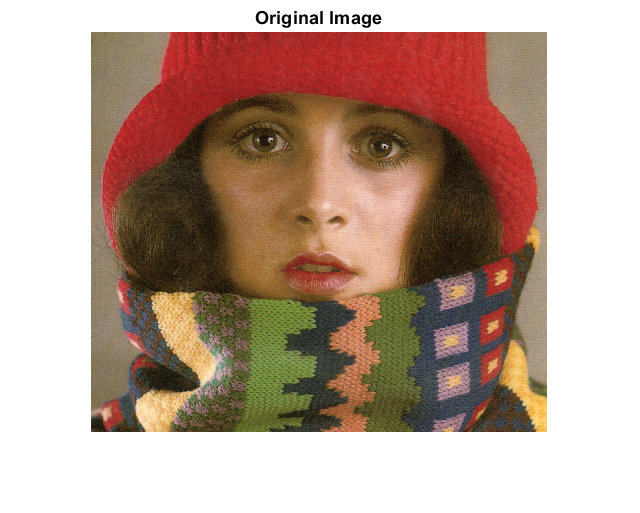

%
for x = 1: size(ci, 1)
    for y = 1: size(ci, 2)
        red = ci(x, y, 1);
        green = ci(x, y, 2);
        blue = ci(x, y, 3);
        
        %Red Channel
        if temp <= 66 
            red = 255;
        else
            red = temp - 60;
            red = 329.698727446 * (red ^ -0.1332047592);
            if red < 0
                red = 0;
            elseif red > 255
                red = 255;
            end
        end
        
        %Green Channel
        if temp <= 66
            green = temp;
            green = 99.4708025861 * log(green) - 161.1195681661;
            if green < 0
                green = 0;
            elseif green > 255
                green = 255;
            end
        else 
            green = temp - 60;
            green = 288.1221695283 * (green ^ -0.0755148492);
            if green < 0
                green = 0;
            elseif green > 255
                green = 255;
            end
        end
        
        %Blue Channel
        if temp >= 66
            blue = 255;
        else
            if temp <= 19
                blue = 0;
            else
                blue = temp - 10;
                blue = 138.5177312231 * log(blue) - 305.0447927307;
                if blue < 0
                    blue = 0;
                elseif blue > 255
                    blue = 255;
                end
            end
        end
        
        cout(x, y , 1) = red;
        cout(x, y , 1) = green;
        cout(x, y , 1) = blue;      
    end
end

imshow(ci), title('Original Image')

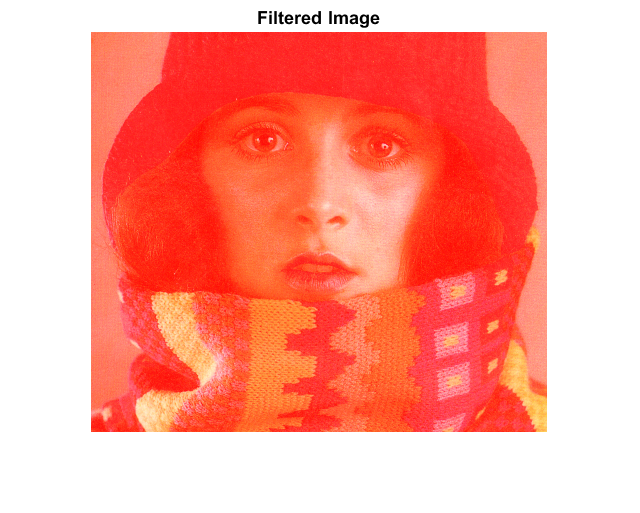

imshow(cout), title('Filtered Image')